# Summary Results Demo

Use `SummaryResults` function to compare the costs values for the diferent states of the plant

#### Select and read the data model file

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(filename);

#### Select the parameters

Select the `Resource Sample` parameter to compute the cost, and activate `Show `parameter to show the results.

param=struct();
if data.isResourceCost
    Samples=convertCharsToStrings(data.SampleNames);
    param.ResourceSample=convertStringsToChars(Samples(1));
end
param.Show=true;

#### Get the Summary Results

res=SummaryResults(data,param);

Flows Exergy (kW) - SUMMARY

 Key            REF      TRB75     PBLR18      PCND2      PCND3      noIHE
———————————————————————————————————————————————————————————————————————————
 B1          83.570     89.430     83.930     87.640    108.000     83.570
 B2          17.900     19.540     18.460     21.920     41.990     17.900
 B3          15.790     16.940     16.390     19.590     38.680     17.900
 B4           5.784      6.190      6.011      6.340      9.990      5.784
 B5           7.877      8.430      7.948      8.528     12.620      7.877
 B6           9.420     10.310      9.471     10.330     15.490      7.877
 QBLR       100.000    106.300    100.800    103.500    120.200    106.900
 WP           2.447      2.619      2.264      2.554      3.053      2.447
 WN          50.000     50.000     50.000     50.000     50.000     50.000
 QCND        10.006     10.750     10.379     13.250     28.690     12.116


Process Unit Consumption (J/J) - SUMMARY

 Key           REF      TR

Flows Exergy (kW) - SUMMARY

 Key            REF      TRB75     PBLR18      PCND2      PCND3      noIHE
———————————————————————————————————————————————————————————————————————————
 B1          83.570     89.430     83.930     87.640    108.000     83.570
 B2          17.900     19.540     18.460     21.920     41.990     17.900
 B3          15.790     16.940     16.390     19.590     38.680     17.900
 B4           5.784      6.190      6.011      6.340      9.990      5.784
 B5           7.877      8.430      7.948      8.528     12.620      7.877
 B6           9.420     10.310      9.471     10.330     15.490      7.877
 QBLR       100.000    106.300    100.800    103.500    120.200    106.900
 WP           2.447      2.619      2.264      2.554      3.053      2.447
 WN          50.000     50.000     50.000     50.000     50.000     50.000
 QCND        10.006     10.750     10.379     13.250     28.690     12.116


Process Unit Consumption (J/J) - SUMMARY

 Key           REF      TR

#### Show the default summary results graph

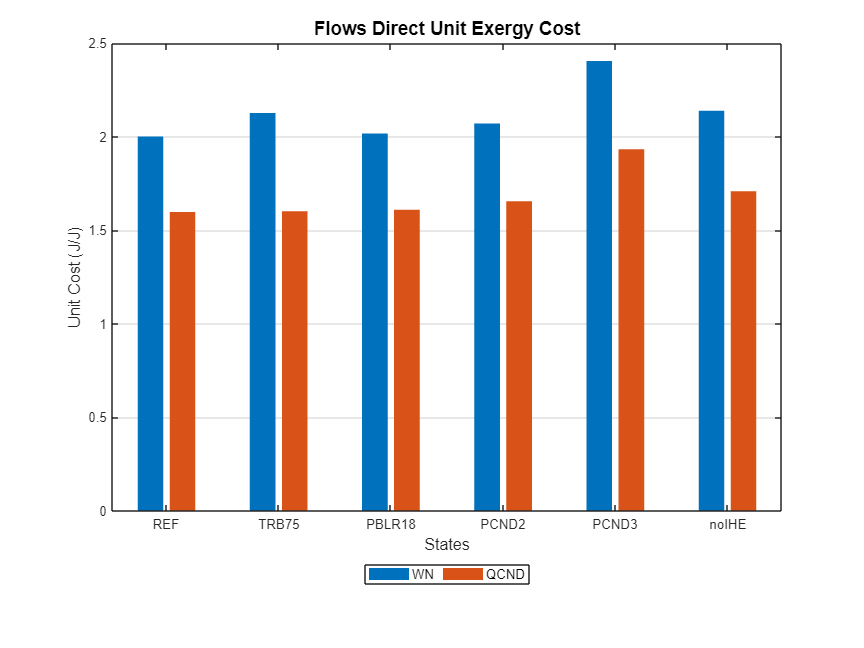

ShowGraph(res);

#### Save the summary results into an excel file

outfile='SummaryResults.xlsx';
SaveOption=false;
if SaveOption
    SaveResults(model,outfile);
end

**Additional Help**

help SummaryResults

 SummaryResults - Gets the summary cost results for a plant.
    This function retrieves the summary tables comparing the efficiency
    and cost results for each state defined in the exergy data model.
 
  Syntax
    res=SummaryResults(data,Name,Value)
 
  Input Arguments
    data - cReadModel object containing the data model
 
  Name-Value Arguments
    ResourceSample - Select a sample in ResourcesCost table. If missing first sample is taken
      char array
    Show -  Show results on console
      true | false (default)
    SaveAs - Name of the file to save the results
      char array | string
 
  Output Arguments
    res - cResultInfo object with the summary results
     It contains the following tables:
       Exergy of the states (exergy)
       Unit consumption of the processes (pku)
       Direct Cost of the processes (dpc)
       Direct unit cost of the processes (dpuc)
       Direct flows cost (dfc)
       Direct unit flow costs (dfuc)
    